# Resting-State Pre-Processing

This script provides sections to pre-process and clean the data collected from the **Resting State**. The following provides a breakdown of the section. All codes can be run independently of each other.

Sections related to scalp-EEG:

- Section 1: allows the obtention of configurations T7-Oz and T8-Oz

- Section 2: allows the obtention of configuration T7-T8

Sections related to ear-EEG:

- Section 3: allows the obtention of the ear configuration 

## Scalp EEG

## Section 1: Configurations T7-Oz and T8-Oz


Processing Participant 1...


Unable to compile, falling back to slower uncompiled code.


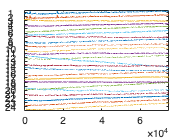

Participant 1 processed.


% Plotting settings for ALL CHANNELS – multiplying columns per rows must be
% equal to number of channels
columns = 4;
rows = 6;
grey = [0, 0, 0, 0.4];

% Pwelch/Spectrogram Parameters – ASSR/SSVEP and Alpha Block
n = 2; % seconds for window
nominal_fs = 250;  % default nominal_fs (will be overwritten by file info)
window = nominal_fs * n;
noverlap = window/2; % 50% overlap
nfft = 2^nextpow2(window); % next power of 2 after window size

% Epoch window and latency interval – estimated with the MBT jitterbox
latency = -8;       % ms, to account for system stimuli output latency
baseline_time = 200; % ms
analysis_time = 500; % ms

% 3–tap, moving mean filter (if used)
smooth_filter = [1/3, 1/3, 1/3];

% Plots per figure
channels_figure = columns * rows;

% Number of participants to process
n_participants = 1;

%% Loop through every participant

for participant = 1:n_participants
    fprintf('\nProcessing Participant %d...\n', participant);
    
    % --- File Selection and Data Loading ---
    [file_name, file_path] = uigetfile('*.xdf*', sprintf('Select the XDF file for participant %d', participant));
    if isequal(file_name, 0)
        warning('No file selected for participant %d. Skipping...', participant);
        continue;
    end
    full_file_path = fullfile(file_path, file_name);
    xdf_data = load_xdf(full_file_path);
    
    % --- Stream IDs ---
    marker_stream_id = input(sprintf('Enter marker stream id for participant %d: ', participant));
    data_stream_id   = input(sprintf('Enter data stream id for participant %d: ', participant));
    
    % --- Data Extraction from XDF Structure ---
    eeg_data            = xdf_data{data_stream_id}.time_series;
    eeg_data_timestamps = xdf_data{data_stream_id}.time_stamps;
    marker_stream       = xdf_data{marker_stream_id}.time_series;
    marker_timestamps   = xdf_data{marker_stream_id}.time_stamps;
    
    % Get sampling rate and number of channels from file info
    nominal_fs = floor(str2double(xdf_data{data_stream_id}.info.nominal_srate));
    fs         = 250;
    n_channels = str2double(xdf_data{data_stream_id}.info.channel_count);
    
    % Create channel labels based on device type.
    if n_channels == 1
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1) = 'In-Ear Single-Channel';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    elseif n_channels == 24
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1)  = 'Fp1';
        channelLabels(2)  = 'Fp2';
        channelLabels(3)  = 'F3';
        channelLabels(4)  = 'F4';
        channelLabels(5)  = 'C3';
        channelLabels(6)  = 'C4';
        channelLabels(7)  = 'P3';
        channelLabels(8)  = 'P4';
        channelLabels(9)  = 'O1';
        channelLabels(10) = 'O2';
        channelLabels(11) = 'F7';
        channelLabels(12) = 'F8';
        channelLabels(13) = 'T7';
        channelLabels(14) = 'T8';
        channelLabels(15) = 'P7';
        channelLabels(16) = 'P8';
        channelLabels(17) = 'Fz';
        channelLabels(18) = 'Cz';
        channelLabels(19) = 'Pz';
        channelLabels(20) = 'M1';
        channelLabels(21) = 'M2';
        channelLabels(22) = 'AFz';
        channelLabels(23) = 'CPz';
        channelLabels(24) = 'POz';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    else
        channels = strings(n_channels, 1);
        for i = 1:n_channels
            channels(i) = sprintf('Ch%d', i);
        end
    end
    
    figures = ceil(n_channels/channels_figure);
    
    %% Extract the EEG Segment 
    start_marker = 'resting_start';
    end_marker   = 'resting_end';
    
    %% isue with P9 is here
    start_marker_index = find(strcmp(marker_stream, start_marker), 1);
    end_marker_index   = find(strcmp(marker_stream, end_marker), 1);
    
    start_time = marker_timestamps(start_marker_index);
    end_time   = marker_timestamps(end_marker_index);
    
    [~, start_index] = min(abs(eeg_data_timestamps - start_time));
    [~, end_index]   = min(abs(eeg_data_timestamps - end_time));
    
    data = eeg_data(:, start_index:end_index);
    data_timestamps = eeg_data_timestamps(start_index:end_index);

    % Gets stimuli or other markers and their timestamps for this paradigm
    markers = marker_stream(start_marker_index + 1:end_marker_index - 1);
    markers_timestamps = marker_timestamps(start_marker_index + 1:end_marker_index - 1);
    
    %% Preprocessing: Filtering and Referencing

    fc_high = 1;    % Highpass cut-off
    fc_low  = 100;  % Lowpass cut-off
    
    data = double(data);
    Complot(data - mean(data, 2));  % Optional plot for quality check
    
    filtered_data  = zeros(size(data));
    processed_data = zeros(size(data));
    
    % Highpass Filtering
    [b, a] = butter(4, fc_high/(nominal_fs/2), 'high');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, data(ch, :));
    end
    
    % Notch Filtering (50 Hz)
    f_notch = 50;
    Q       = 35;
    wo      = f_notch/(nominal_fs/2);
    bw      = wo/Q;
    [b, a] = iirnotch(wo, bw);
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    
    % Lowpass Filtering
    [b, a] = butter(4, fc_low/(nominal_fs/2), 'low');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Reference the data

    ref_channel = 24; % input

    ref_data = filtered_data(ref_channel,:);

    for i = 1:n_channels
        if i == ref_channel
            continue
        else
            processed_data(i,:) = filtered_data(i,:) - ref_data;
        end
    end
    

    % Save the data for channels 13 and 14 (T7 and T8):
    channel_T7_data = processed_data(13, :);
    channel_T8_data = processed_data(14, :);
    
    % Hold data for the current participant
    participant_data = struct();
    participant_data.channel_T7 = channel_T7_data;
    participant_data.channel_T8 = channel_T8_data;
    
   
    % Save data for participant
    combined_filename = sprintf('Participant_%d_T7andT8_refPOz_RS.mat');
    save(combined_filename, 'participant_data');
    
    fprintf('Participant %d processed.\n', participant);
end

## Section 2: Configuration T7-T8


Processing Participant 1...


Unable to compile, falling back to slower uncompiled code.


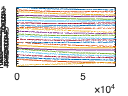

Participant 1 processed.


% Plotting settings for ALL CHANNELS – multiplying columns per rows must be
% equal to number of channels
columns = 4;
rows = 6;
grey = [0, 0, 0, 0.4];

% Pwelch/Spectrogram Parameters – ASSR/SSVEP and Alpha Block
n = 2; % seconds for window
nominal_fs = 250;  % default nominal_fs (will be overwritten by file info)
window = nominal_fs * n;
noverlap = window/2; % 50% overlap
nfft = 2^nextpow2(window); % next power of 2 after window size

% Epoch window and latency interval – estimated with the MBT jitterbox
latency = -8;       % ms, to account for system stimuli output latency
baseline_time = 200; % ms
analysis_time = 500; % ms


% 3–tap, moving mean filter (if used)
smooth_filter = [1/3, 1/3, 1/3];

% Plots per figure
channels_figure = columns * rows;

% Number of participants to process
n_participants = 1;

%% Loop through every participant

for participant = 1:n_participants
    fprintf('\nProcessing Participant %d...\n', participant);
    
    % --- File Selection and Data Loading ---
    [file_name, file_path] = uigetfile('*.xdf*', sprintf('Select the XDF file for participant %d', participant));
    if isequal(file_name, 0)
        warning('No file selected for participant %d. Skipping...', participant);
        continue;
    end
    full_file_path = fullfile(file_path, file_name);
    xdf_data = load_xdf(full_file_path);
    
    % --- Stream IDs ---
    marker_stream_id = input(sprintf('Enter marker stream id for participant %d: ', participant));
    data_stream_id   = input(sprintf('Enter data stream id for participant %d: ', participant));
    
    % --- Data Extraction from XDF Structure ---
    eeg_data            = xdf_data{data_stream_id}.time_series;
    eeg_data_timestamps = xdf_data{data_stream_id}.time_stamps;
    marker_stream       = xdf_data{marker_stream_id}.time_series;
    marker_timestamps   = xdf_data{marker_stream_id}.time_stamps;
    
    % Get sampling rate and number of channels from file info
    nominal_fs = floor(str2double(xdf_data{data_stream_id}.info.nominal_srate));
    fs         = 250;
    n_channels = str2double(xdf_data{data_stream_id}.info.channel_count);
    
    % Create channel labels based on device type.
    if n_channels == 1
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1) = 'In-Ear Single-Channel';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    elseif n_channels == 24
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1)  = 'Fp1';
        channelLabels(2)  = 'Fp2';
        channelLabels(3)  = 'F3';
        channelLabels(4)  = 'F4';
        channelLabels(5)  = 'C3';
        channelLabels(6)  = 'C4';
        channelLabels(7)  = 'P3';
        channelLabels(8)  = 'P4';
        channelLabels(9)  = 'O1';
        channelLabels(10) = 'O2';
        channelLabels(11) = 'F7';
        channelLabels(12) = 'F8';
        channelLabels(13) = 'T7';
        channelLabels(14) = 'T8';
        channelLabels(15) = 'P7';
        channelLabels(16) = 'P8';
        channelLabels(17) = 'Fz';
        channelLabels(18) = 'Cz';
        channelLabels(19) = 'Pz';
        channelLabels(20) = 'M1';
        channelLabels(21) = 'M2';
        channelLabels(22) = 'AFz';
        channelLabels(23) = 'CPz';
        channelLabels(24) = 'POz';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    else
        channels = strings(n_channels, 1);
        for i = 1:n_channels
            channels(i) = sprintf('Ch%d', i);
        end
    end
    
    figures = ceil(n_channels/channels_figure);
    
    %% Extract the EEG Segment 
    start_marker = 'resting_start';
    end_marker   = 'resting_end';
    
    %% isue with P9 is here
    start_marker_index = find(strcmp(marker_stream, start_marker), 1);
    end_marker_index   = find(strcmp(marker_stream, end_marker), 1);
    
    start_time = marker_timestamps(start_marker_index);
    end_time   = marker_timestamps(end_marker_index);
    
    [~, start_index] = min(abs(eeg_data_timestamps - start_time));
    [~, end_index]   = min(abs(eeg_data_timestamps - end_time));
    
    data = eeg_data(:, start_index:end_index);
    data_timestamps = eeg_data_timestamps(start_index:end_index);

    % Gets stimuli or other markers and their timestamps for this paradigm
    markers = marker_stream(start_marker_index + 1:end_marker_index - 1);
    markers_timestamps = marker_timestamps(start_marker_index + 1:end_marker_index - 1);
    
%% Preprocessing: Filtering and Referencing

    fc_high = 1;    % Highpass cut-off
    fc_low  = 100;  % Lowpass cut-off
    
    data = double(data);
    Complot(data - mean(data, 2));  % Optional plot for quality check
    
    filtered_data  = zeros(size(data));
    processed_data = zeros(size(data));
    
    % Highpass Filtering
    [b, a] = butter(4, fc_high/(nominal_fs/2), 'high');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, data(ch, :));
    end
    
    % Notch Filtering (50 Hz)
    f_notch = 50;
    Q       = 35;
    wo      = f_notch/(nominal_fs/2);
    bw      = wo/Q;
    [b, a] = iirnotch(wo, bw);
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    
    % Lowpass Filtering
    [b, a] = butter(4, fc_low/(nominal_fs/2), 'low');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Reference the data

    ref_channel = 14; % input

    ref_data = filtered_data(ref_channel,:);

    for i = 1:n_channels
        if i == ref_channel
            continue
        else
            processed_data(i,:) = filtered_data(i,:) - ref_data;
        end
    end
    
    % Save the data for channels 13 and 14 (T7 and T8):
    channel_T7_data = processed_data(13, :);
    channel_T8_data = processed_data(14, :);
    
    % Hold data for the current participant
    participant_data = struct();
    participant_data.channel_T7 = channel_T7_data;
    participant_data.channel_T8 = channel_T8_data;
   
    % Save data of the current participant
    combined_filename = sprintf('Participant_%d_T7_refT8_RS.mat', participant);
    save(combined_filename, 'participant_data');
    
    fprintf('Participant %d processed.\n', participant);
end

## Ear EEG Preprocessing


Processing Participant 1...


Unable to compile, falling back to slower uncompiled code.


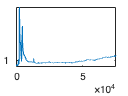

Participant 1 processed.


% Plotting settings for ALL CHANNELS – multiplying columns per rows must be
% equal to number of channels
columns = 4;
rows = 6;
grey = [0, 0, 0, 0.4];

% Pwelch/Spectrogram Parameters – ASSR/SSVEP and Alpha Block
n = 2; % seconds for window
nominal_fs = 250;  % default nominal_fs (will be overwritten by file info)
window = nominal_fs * n;
noverlap = window/2; % 50% overlap
nfft = 2^nextpow2(window); % next power of 2 after window size

% Epoch window and latency interval – estimated with the MBT jitterbox
latency = -8;       % ms, to account for system stimuli output latency
baseline_time = 200; % ms
analysis_time = 500; % ms

% 3–tap, moving mean filter (if used)
smooth_filter = [1/3, 1/3, 1/3];

% Plots per figure
channels_figure = columns * rows;

% Number of participants to process
n_participants = 1;



%% Loop through every participant

for participant = 1:n_participants
    fprintf('\nProcessing Participant %d...\n', participant);
    
    % --- File Selection and Data Loading ---
    [file_name, file_path] = uigetfile('*.xdf*', sprintf('Select the XDF file for participant %d', participant));
    if isequal(file_name, 0)
        warning('No file selected for participant %d. Skipping...', participant);
        continue;
    end
    full_file_path = fullfile(file_path, file_name);
    xdf_data = load_xdf(full_file_path);
    
    % --- Stream IDs ---
    marker_stream_id = input(sprintf('Enter marker stream id for participant %d: ', participant));
    data_stream_id   = input(sprintf('Enter data stream id for participant %d: ', participant));
    
    % --- Data Extraction from XDF Structure ---
    eeg_data            = xdf_data{data_stream_id}.time_series;
    eeg_data_timestamps = xdf_data{data_stream_id}.time_stamps;
    marker_stream       = xdf_data{marker_stream_id}.time_series;
    marker_timestamps   = xdf_data{marker_stream_id}.time_stamps;
    
    % Get sampling rate and number of channels from file info
    nominal_fs = floor(str2double(xdf_data{data_stream_id}.info.nominal_srate));
    fs         = xdf_data{data_stream_id}.segments.effective_srate;
    n_channels = str2double(xdf_data{data_stream_id}.info.channel_count);

    
    % Create channel labels based on device type.
    if n_channels == 1
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1) = 'In-Ear Single-Channel';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    elseif n_channels == 24
        channelLabels = containers.Map('KeyType','single','ValueType','char');
        channelLabels(1)  = 'Fp1';
        channelLabels(2)  = 'Fp2';
        channelLabels(3)  = 'F3';
        channelLabels(4)  = 'F4';
        channelLabels(5)  = 'C3';
        channelLabels(6)  = 'C4';
        channelLabels(7)  = 'P3';
        channelLabels(8)  = 'P4';
        channelLabels(9)  = 'O1';
        channelLabels(10) = 'O2';
        channelLabels(11) = 'F7';
        channelLabels(12) = 'F8';
        channelLabels(13) = 'T7';
        channelLabels(14) = 'T8';
        channelLabels(15) = 'P7';
        channelLabels(16) = 'P8';
        channelLabels(17) = 'Fz';
        channelLabels(18) = 'Cz';
        channelLabels(19) = 'Pz';
        channelLabels(20) = 'M1';
        channelLabels(21) = 'M2';
        channelLabels(22) = 'AFz';
        channelLabels(23) = 'CPz';
        channelLabels(24) = 'POz';
        channels = strings(n_channels, 1);
        keys = channelLabels.keys;
        for i = 1:n_channels
            channels(i) = channelLabels(keys{i});
        end
    else
        channels = strings(n_channels, 1);
        for i = 1:n_channels
            channels(i) = sprintf('Ch%d', i);
        end
    end
    
    figures = ceil(n_channels/channels_figure);
    
   
   %% Extract the EEG Segment
    start_marker = 'resting_start';
    end_marker   = 'resting_end';
    
    %% isue with P9 is here
    start_marker_index = find(strcmp(marker_stream, start_marker), 1);
    end_marker_index   = find(strcmp(marker_stream, end_marker), 1);
    
    start_time = marker_timestamps(start_marker_index);
    end_time   = marker_timestamps(end_marker_index);
    
    [~, start_index] = min(abs(eeg_data_timestamps - start_time));
    [~, end_index]   = min(abs(eeg_data_timestamps - end_time));
    
    data = eeg_data(:, start_index:end_index);
    data_timestamps = eeg_data_timestamps(start_index:end_index);

    % Gets stimuli or other markers and their timestamps for this paradigm
    markers = marker_stream(start_marker_index + 1:end_marker_index - 1);
    markers_timestamps = marker_timestamps(start_marker_index + 1:end_marker_index - 1);
    
    %% Preprocessing: Filtering and Referencing

    fc_high = 1;    % Highpass cut-off
    fc_low  = 100;  % Lowpass cut-off
    
    data = double(data);
    Complot(data - mean(data, 2));  % Optional plot for quality check
    
    filtered_data  = zeros(size(data));
    processed_data = zeros(size(data));
    
    % Highpass Filtering
    [b, a] = butter(4, fc_high/(nominal_fs/2), 'high');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, data(ch, :));
    end
    
    % Notch Filtering (50 Hz)
    f_notch = 50;
    Q       = 35;
    wo      = f_notch/(nominal_fs/2);
    bw      = wo/Q;
    [b, a] = iirnotch(wo, bw);
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    
    % Lowpass Filtering
    [b, a] = butter(4, fc_low/(nominal_fs/2), 'low');
    for ch = 1:size(data, 1)
        filtered_data(ch, :) = filtfilt(b, a, filtered_data(ch, :));
    end
    processed_data = filtered_data;

    % Select and save the data for channels 13 and 14 (T7 and T8):
    ear_data = processed_data(1, :);
    
    % Hold data for the current participant
    participant_data = struct();
    participant_data.ear = ear_data;
    
    % Save data
    combined_filename = sprintf('Participant_%d_ear_RS.mat', participant);
    % Save the struct to a single .mat file
    save(combined_filename, 'participant_data');
    
    fprintf('Participant %d processed.\n', participant);
end